Author: Zarina Akbary

Date: 04 June 2021

Purpose: to walk throug BTColorDecode.m line by line

## BTColorDecode.m

Author: 3/28/19, Rico Rojas

Purpose: To be used after BacTrack.  Decodes multiple strains based on fluorescent labels. Save color decode images as an image sequence in a separate directory with phase image first.

This code start the way most other code starts: user input as to which folders your data is located in. For this demonstration, I've made a few modifications to the original code to enable a proper analysis (for instance, I set T=122 because the traces after hyperosmotic shock are less smooth and I haven't found the bug in LinTrack). 

%INPUT%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
basename='05262021_Exp1'; legend_str={'GFP','TADA'}; thresholds=[1500 1250];  t1=[15 27 39 51 63];  t2=[17 29 41 53 66];%Plasmolysis lysis of MG1655, KB242, EHEC pooled, occlusion microscopy
%basename='032819_5', legend_str={'EHEC','MG1655','KB242'},thresholds=[2000 1200], t1=[13 28 40 52 64];  t2=[15 30 42 55 67];;%Plasmolysis lysis of MG1655, KB242, EHEC pooled, occlusion microscopy
%basename='032819_7',legend_str={'MG1655','KB242','EHEC'},thresholds=[400 1000], t1=[13 25 37 49 60];  t2=[15 27 39 52 63];%Plasmolysis lysis of MG1655, KB242, EHEC pooled, occlusion microscopy

ncolors=3;%Number of channels including dark cells

movie_directory=['/Users/zarina/Downloads/NYU/Year2_2021_Spring/05262021_analysis/' basename '/' basename '_phase/' basename '_erased'];%Directory in which movie is saved
color_directory=['/Users/zarina/Downloads/NYU/Year2_2021_Spring/05262021_analysis/' basename];%Directory in which color 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


curdir=cd;
cd(color_directory); 
fluo_directory=dir('*.tif');
cd(movie_directory); 
phase_directory=dir('*.tif');

cd([color_directory '/' basename '_phase/' basename '_figures']); 
load([basename '_BTphase'],'T','pixels','v','lcell','tmid','ncells','B')

T=122;
T=122;
pixels=pixels(:,1:T);
B=B(:,1:T);
v=v(:,1:T);
lcell=lcell(:, 1:T);
tmid=tmid(:,1:T);

Now, let's read the images. Below is TestIm and RefIm on the left and right, respectively.

cd(color_directory); 
imagename=fluo_directory(1).name;
TestIm=imread(imagename);
cd(movie_directory); 
imagename=phase_directory(T).name;
RefIm=imread(imagename);

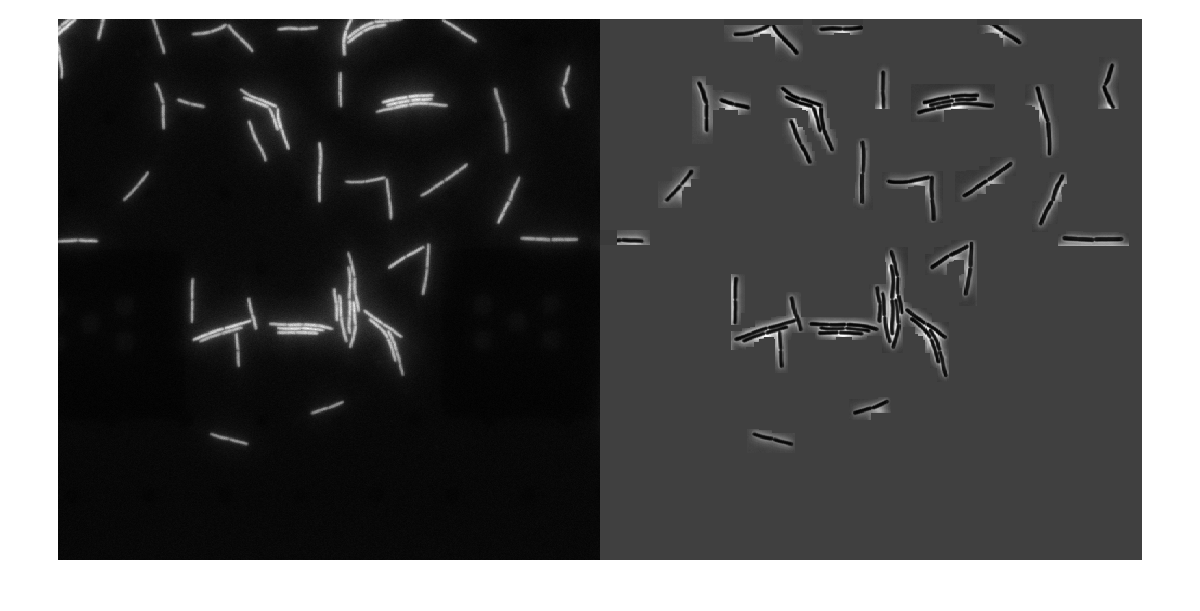I'm not sure what this part of the code does.

[output NewImFT]=dftregistration(fft2(RefIm),fft2(TestIm),10);
NewIm=abs(ifft2(NewImFT));
shft(1)=output(3);
shft(2)=output(4);

vav_col=zeros(ncolors,T-1);

This is the code for the dtfregistration function and I think it aligns the images and performs a Fourier transformation.

% function [output Greg] = dftregistration(buf1ft,buf2ft,usfac)   
% % function [output Greg] = dftregistration(buf1ft,buf2ft,usfac);
% % Efficient subpixel image registration by crosscorrelation. This code
% % gives the same precision as the FFT upsampled cross correlation in a
% % small fraction of the computation time and with reduced memory 
% % requirements. It obtains an initial estimate of the crosscorrelation peak
% % by an FFT and then refines the shift estimation by upsampling the DFT
% % only in a small neighborhood of that estimate by means of a 
% % matrix-multiply DFT. With this procedure all the image points are used to
% % compute the upsampled crosscorrelation.
% % Manuel Guizar - Dec 13, 2007
% 
% % Portions of this code were taken from code written by Ann M. Kowalczyk 
% % and James R. Fienup. 
% % J.R. Fienup and A.M. Kowalczyk, "Phase retrieval for a complex-valued 
% % object by using a low-resolution image," J. Opt. Soc. Am. A 7, 450-458 
% % (1990).
% 
% % Citation for this algorithm:
% % Manuel Guizar-Sicairos, Samuel T. Thurman, and James R. Fienup, 
% % "Efficient subpixel image registration algorithms," Opt. Lett. 33, 
% % 156-158 (2008).
% 
% % Inputs
% % buf1ft    Fourier transform of reference image, 
% %           DC in (1,1)   [DO NOT FFTSHIFT]
% % buf2ft    Fourier transform of image to register, 
% %           DC in (1,1) [DO NOT FFTSHIFT]
% % usfac     Upsampling factor (integer). Images will be registered to 
% %           within 1/usfac of a pixel. For example usfac = 20 means the
% %           images will be registered within 1/20 of a pixel. (default = 1)
% 
% % Outputs
% % output =  [error,diffphase,net_row_shift,net_col_shift]
% % error     Translation invariant normalized RMS error between f and g
% % diffphase     Global phase difference between the two images (should be
% %               zero if images are non-negative).
% % net_row_shift net_col_shift   Pixel shifts between images
% % Greg      (Optional) Fourier transform of registered version of buf2ft,
% %           the global phase difference is compensated for.
% 
% % Default usfac to 1
% if exist('usfac')~=1, usfac=1; end
% 
% % Compute error for no pixel shift
% if usfac == 0,
%     CCmax = sum(sum(buf1ft.*conj(buf2ft))); 
%     rfzero = sum(abs(buf1ft(:)).^2);
%     rgzero = sum(abs(buf2ft(:)).^2); 
%     error = 1.0 - CCmax.*conj(CCmax)/(rgzero*rfzero); 
%     error = sqrt(abs(error));
%     diffphase=atan2(imag(CCmax),real(CCmax)); 
%     output=[error,diffphase];
%         
% % Whole-pixel shift - Compute crosscorrelation by an IFFT and locate the
% % peak
% elseif usfac == 1,
%     [m,n]=size(buf1ft);
%     CC = ifft2(buf1ft.*conj(buf2ft));
%     [max1,loc1] = max(CC);
%     [max2,loc2] = max(max1);
%     rloc=loc1(loc2);
%     cloc=loc2;
%     CCmax=CC(rloc,cloc); 
%     rfzero = sum(abs(buf1ft(:)).^2)/(m*n);
%     rgzero = sum(abs(buf2ft(:)).^2)/(m*n); 
%     error = 1.0 - CCmax.*conj(CCmax)/(rgzero(1,1)*rfzero(1,1));
%     error = sqrt(abs(error));
%     diffphase=atan2(imag(CCmax),real(CCmax)); 
%     md2 = fix(m/2); 
%     nd2 = fix(n/2);
%     if rloc > md2
%         row_shift = rloc - m - 1;
%     else
%         row_shift = rloc - 1;
%     end
% 
%     if cloc > nd2
%         col_shift = cloc - n - 1;
%     else
%         col_shift = cloc - 1;
%     end
%     output=[error,diffphase,row_shift,col_shift];
%     
% % Partial-pixel shift
% else
%     
%     % First upsample by a factor of 2 to obtain initial estimate
%     % Embed Fourier data in a 2x larger array
%     [m,n]=size(buf1ft);
%     mlarge=m*2;
%     nlarge=n*2;
%     CC=zeros(mlarge,nlarge);
%     CC(m+1-fix(m/2):m+1+fix((m-1)/2),n+1-fix(n/2):n+1+fix((n-1)/2)) = ...
%         fftshift(buf1ft).*conj(fftshift(buf2ft));
%   
%     % Compute crosscorrelation and locate the peak 
%     CC = ifft2(ifftshift(CC)); % Calculate cross-correlation
%     [max1,loc1] = max(CC);
%     [max2,loc2] = max(max1);
%     rloc=loc1(loc2);cloc=loc2;
%     CCmax=CC(rloc,cloc);
%     
%     % Obtain shift in original pixel grid from the position of the
%     % crosscorrelation peak 
%     [m,n] = size(CC); md2 = fix(m/2); nd2 = fix(n/2);
%     if rloc > md2 
%         row_shift = rloc - m - 1;
%     else
%         row_shift = rloc - 1;
%     end
%     if cloc > nd2
%         col_shift = cloc - n - 1;
%     else
%         col_shift = cloc - 1;
%     end
%     row_shift=row_shift/2;
%     col_shift=col_shift/2;
% 
%     % If upsampling > 2, then refine estimate with matrix multiply DFT
%     if usfac > 2,
%         %%% DFT computation %%%
%         % Initial shift estimate in upsampled grid
%         row_shift = round(row_shift*usfac)/usfac; 
%         col_shift = round(col_shift*usfac)/usfac;     
%         dftshift = fix(ceil(usfac*1.5)/2); %% Center of output array at dftshift+1
%         % Matrix multiply DFT around the current shift estimate
%         CC = conj(dftups(buf2ft.*conj(buf1ft),ceil(usfac*1.5),ceil(usfac*1.5),usfac,...
%             dftshift-row_shift*usfac,dftshift-col_shift*usfac))/(md2*nd2*usfac^2);
%         % Locate maximum and map back to original pixel grid 
%         [max1,loc1] = max(CC);   
%         [max2,loc2] = max(max1); 
%         rloc = loc1(loc2); cloc = loc2;
%         CCmax = CC(rloc,cloc);
%         rg00 = dftups(buf1ft.*conj(buf1ft),1,1,usfac)/(md2*nd2*usfac^2);
%         rf00 = dftups(buf2ft.*conj(buf2ft),1,1,usfac)/(md2*nd2*usfac^2);  
%         rloc = rloc - dftshift - 1;
%         cloc = cloc - dftshift - 1;
%         row_shift = row_shift + rloc/usfac;
%         col_shift = col_shift + cloc/usfac;    
% 
%     % If upsampling = 2, no additional pixel shift refinement
%     else    
%         rg00 = sum(sum( buf1ft.*conj(buf1ft) ))/m/n;
%         rf00 = sum(sum( buf2ft.*conj(buf2ft) ))/m/n;
%     end
%     error = 1.0 - CCmax.*conj(CCmax)/(rg00*rf00);
%     error = sqrt(abs(error));
%     diffphase=atan2(imag(CCmax),real(CCmax));
%     % If its only one row or column the shift along that dimension has no
%     % effect. We set to zero.
%     if md2 == 1,
%         row_shift = 0;
%     end
%     if nd2 == 1,
%         col_shift = 0;
%     end
%     output=[error,diffphase,row_shift,col_shift];
% end  
% 
% % Compute registered version of buf2ft
% if (nargout > 1)&&(usfac > 0),
%     [nr,nc]=size(buf2ft);
%     Nr = ifftshift([-fix(nr/2):ceil(nr/2)-1]);
%     Nc = ifftshift([-fix(nc/2):ceil(nc/2)-1]);
%     [Nc,Nr] = meshgrid(Nc,Nr);
%     Greg = buf2ft.*exp(i*2*pi*(-row_shift*Nr/nr-col_shift*Nc/nc));
%     Greg = Greg*exp(i*diffphase);
% elseif (nargout > 1)&&(usfac == 0)
%     Greg = buf2ft*exp(i*diffphase);
% end
% return
% 
% function out=dftups(in,nor,noc,usfac,roff,coff)
% % function out=dftups(in,nor,noc,usfac,roff,coff);
% % Upsampled DFT by matrix multiplies, can compute an upsampled DFT in just
% % a small region.
% % usfac         Upsampling factor (default usfac = 1)
% % [nor,noc]     Number of pixels in the output upsampled DFT, in
% %               units of upsampled pixels (default = size(in))
% % roff, coff    Row and column offsets, allow to shift the output array to
% %               a region of interest on the DFT (default = 0)
% % Recieves DC in upper left corner, image center must be in (1,1) 
% % Manuel Guizar - Dec 13, 2007
% % Modified from dftus, by J.R. Fienup 7/31/06
% 
% % This code is intended to provide the same result as if the following
% % operations were performed
% %   - Embed the array "in" in an array that is usfac times larger in each
% %     dimension. ifftshift to bring the center of the image to (1,1).
% %   - Take the FFT of the larger array
% %   - Extract an [nor, noc] region of the result. Starting with the 
% %     [roff+1 coff+1] element.
% 
% % It achieves this result by computing the DFT in the output array without
% % the need to zeropad. Much faster and memory efficient than the
% % zero-padded FFT approach if [nor noc] are much smaller than [nr*usfac nc*usfac]
% 
% [nr,nc]=size(in);
% % Set defaults
% if exist('roff')~=1, roff=0; end
% if exist('coff')~=1, coff=0; end
% if exist('usfac')~=1, usfac=1; end
% if exist('noc')~=1, noc=nc; end
% if exist('nor')~=1, nor=nr; end
% % Compute kernels and obtain DFT by matrix products
% kernc=exp((-i*2*pi/(nc*usfac))*( ifftshift([0:nc-1]).' - floor(nc/2) )*( [0:noc-1] - coff ));
% kernr=exp((-i*2*pi/(nr*usfac))*( [0:nor-1].' - roff )*( ifftshift([0:nr-1]) - floor(nr/2)  ));
% out=kernr*in*kernc;
% return